# RobotTugFSM.mlx is a hardware-in-the-loop simulation of a robot tug

This code controls an autonomous robot boat through a simulated mission in theLPB water testing tank.

The fundamental difference between a control system and a robotic system is that control systems do not 'think' about what to do next. Given on set of inputs, it will always generate the same out.put A robot system will take that same set of inputs, consider multiple responses and choose the best output to accomplish the mission. This script will give you hands-on experience with a **classical pure-pursuit control system**, then its sister program **RobotTugThinkLab** will perform the same mission with a behavior-based robot controller that blends multiple synchronous robot behaviors to more robustly accomplish thte same goal.

Written (pair programmed) by CJ Hilty and Ben Morris 2022. Rev A.

close all; % close any open figure windows
clc     % clear command window
clear   % clear MATLAB workspace

### **Set up robot control system** (code that runs once)

Set up the Raspberry Pi to control the tug. Call **TugRaspPiSetup **function to create and configure the Pi. 

make sure you have the **TugRaspPiSetup** function in the local directory

disp("Downloading code to Raspberry Pi may take about 10 seconds.")

[robotPi,rudderServo,propServo,blinkLED,cam]=TugRaspPiSetup();

make sure you have the **TestPool.png** image in the local directory.

img=imread('TestPool.png');             % load test pool image (from local directory)
grayimage=im2gray(img);                 % convert to grayscale
bwimage=grayimage < 0.5;                % convert to black and white
MapOfOval = binaryOccupancyMap(bwimage,10); % convert to a binary occupancy map in meters
% show(MapOfPool);                      % show map

%Inflate map so robot can be treated as a point.
%Assume robot is 0.25m square.
MapOfPoolInflated = copy(MapOfOval);    % make a copy without overwriting original data
inflate(MapOfPoolInflated,0.25);        % dilate the map to accommodate robot size

% To prevent unexpected display glitches in the livescript window,
% create a free-floating figure for the maps to display simulation updates
testPool = figure('name','testPool','NumberTitle','off','Visible','on');
figure(testPool);                      % go to testPool figure for next plot
    show(MapOfPoolInflated)             % show new map in a figure window
    grid on; grid minor;                % set plot properties

Create an IR-based map of the world that will be filled as the Rover drives around the Oval

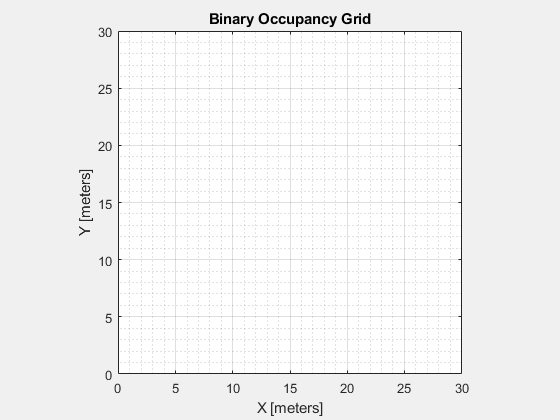

% Create an empty map of the same dimensions as the test pool occupancy map
[mapdimx,mapdimy] = size(bwimage);      % find and store size of map
sharpIRmap = binaryOccupancyMap(mapdimx,mapdimy,10,'grid');% make empty map of same size

% create another free-floating figure for map updates to avoid livescript display glitches
tugSharpIRScan = figure('name','TugSharpIRScan','NumberTitle','off','Visible','on');
figure(tugSharpIRScan);
    show(sharpIRmap);                   % display the figure
    grid on; grid minor;                % set grid options


% note: map figure should be blank to start and it will be populated later.

Create a simulated differential drive robot rover. Inputs are robot vehicle speed and heading.

diffDriveTug = differentialDriveKinematics('vehicleInputs','VehicleSpeedHeadingRate');

Create a pure pursuit Tug controller (this controller generates the required speed and heading values needed to follow a path. It can incorporate a desired linear velocity (m/s) and maximum angular velocity (radians/sec)

TugController = controllerPurePursuit('DesiredLinearVelocity',2,'MaxAngularVelocity',3);

Create a simulated 180° sharp IR range sensor for the Tug. It should have a **max range of 10 meters**.

- The sensor simulates readings for a given pose on a map. In this case, it will be the Olin pool.

- The rangeSensor function has scarce documentation. On the function right-click> help or f1 is useful.

- The simulated IR will simulate range readings from an IR based on position and location on a map.

sharpIRPod = rangeSensor;        % create a simulated rangeSensor object
sharpIRPod.Range = [0.1,10];     % set minimum and maximum range of sensor
sharpIRPod.HorizontalAngle = [-pi/2, pi/2]      % sets each sensor's detection angle

sharpIRPod =   rangeSensor with properties:

                        Range: [0.1000 10]
              HorizontalAngle: [-1.5708 1.5708]
    HorizontalAngleResolution: 0.0244
                   RangeNoise: 0
         HorizontalAngleNoise: 0
                  NumReadings: 129


sharpIRPod.HorizontalAngleResolution = 0.628318 % resolution that sizes 6 sensors to proper map viewing size

sharpIRPod =   rangeSensor with properties:

                        Range: [0.1000 10]
              HorizontalAngle: [-1.5708 1.5708]
    HorizontalAngleResolution: 0.6283
                   RangeNoise: 0
         HorizontalAngleNoise: 0
                  NumReadings: 6


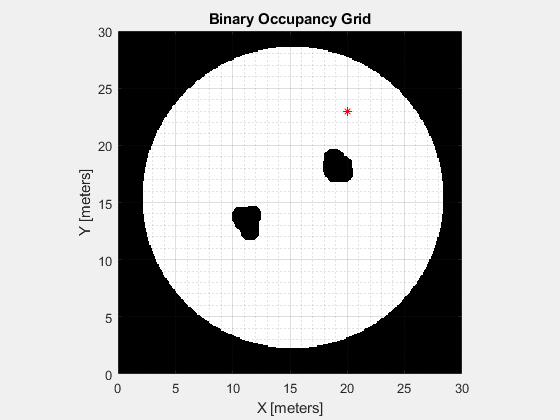

testPose = [20 20 pi/2];    % set an initial test position for IR

% Plot the test spot for the simulated IR scan on the test pool occupancy map
figure(testPool)           % select the testPool map figure for drawing
hold on;
plot(20,23, 'r*');          %plot robot position in pool
hold off;

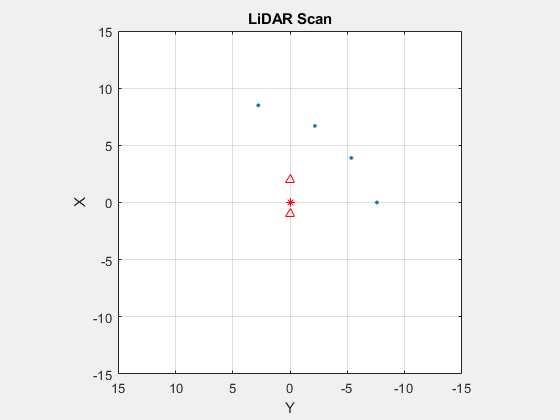


% Generate a IR test scan from the test position defined above in testPose
    [ranges,angles] = sharpIRPod(testPose, MapOfPoolInflated);
    scan = lidarScan(ranges, angles);

% Visualize the test IR scan from the robot's coordinate system
% by creating a new free-standing figure with the robot at the center
% and plotting the local IR scan on that figure.
    localSharpIRPlot = figure('Name','localSharpIRMap','NumberTitle','off','Visible','on');
    figure(localSharpIRPlot);
    plot(scan);
    axis([-15 15 -15 15])
    hold on;
    plot(0,0,'r*');     % plot robot position
    plot(-1,0,'r^');    % plot robot position
    plot(-2,0,'r^');    % plot robot position
    hold off;    

% path = [20 23; 15 23; 10 23; 5 15; 10 10; 15 10; 25 15];    % clear path waypoints
%path = [20 23; 15 23; 10 23; 5 15; 15 12; 20 10; 25 15]    % collision waypoints
%path = [20 20; 25 25]; % short matrix of waypoints to test stopping precision
% Plot the waypoints as a path on the OlinOvalMap occupancy map
% figure(testPool);                          % select the testPool figure
% hold on;
% plot(path(:,1),path(:,2),'o-');             % Plot the points from the matrix of waypoints
% hold off;

Use the waypoints in the **path** variable as the waypoints the Pure Pursuit controller will follow

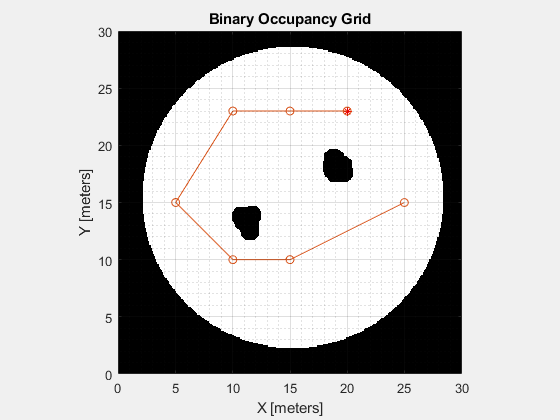

% TugController.Waypoints = path;       %Set rover waypoints

Create a free floating figure for robot behavior brainwave display

brainWaves = figure('name', 'Behavior Brain Waves', 'NumberTitle','off', 'Visible','on');
figure(brainWaves);
pbrain = plot([-3 -2 -1 0 1 2 3], [0 0 0 0 0 0 0]);
axis([-4 4 -4 4]);
grid on;
grid minor;

Set the initial pose and final goalWayPoint location from points in the **path** variable, then create global variables for storing the current pose and an index for tracking loop count.

initTugPose = [path(1,1) path(1,2) pi/2]; % Store initial location and orientation, aka pose
goalWayPoint = [path(end,1) path(end,2)]';  % why "'"? > Sets target end waypoint
sampleTime = 0.10;                          % Sample time (seconds)
t = 0:sampleTime:100;                       % Time array
robotPoses = zeros(3,length(t));            % Preallocate arrray for robot Poses
robotPoses(:,1) = initTugPose';           % Add initial robot pose to robot Poses array
r = rateControl(1/sampleTime);
reset(r);
tolerance = 0.1;                            % In meters, the minimum distance from the final waypoint to finish routine

Arrange figure windows for easy viewing, ask the operator if they are ready and give start options

iptwindowalign(testPool,'right',tugSharpIRScan,'left')

iptwindowalign(tugSharpIRScan,'bottom',localSharpIRPlot,'top');
iptwindowalign(testPool,'right',localSharpIRPlot,'left');

runRover = input('Press CTRL + C to abort, or\nWhen ready, press 1 and then ENTER to run tug.\n')

runRover = 1

### **Run robot control loop **(code that runs over and over)

controlIndex = 1;                           % creates a loop control to limit number of total loops
behaviorCycleTime = 0;                      % create a resetable behavior clock
followClock = 0;                            % create a whale following clock
vStraight = [0 0 0 0 0 0 0];                % create straight behavior vel vector
wStraight = [0 0 0 0 0 0 0];                % create straight behavior w vector
vTurn = [0 0 0 0 0 0 0];                    % create turn behavior vel vector
wTurn = [0 0 0 0 0 0 0];                    % create turn behavior w vector
vAvoid = [0 0 0 0 0 0 0];                   % create avoid behavior vel vector
wAvoid = [0 0 0 0 0 0 0];                   % create avoid behavior w vector
legTime = 20;                               % create random legtime variable
vRef = 0;                                   % initial tug velocity
wRef = 0;                                   % initial tug rotation rate

while(controlIndex < numel(t))              % Loop for number of timesteps in operating procedure
    position = robotPoses(:,controlIndex)'; % gets current robot x,y, and angle
    roverLocation = position(1:2);          % extracts rover x and y from position variable
    %End the loop if rover has reached goal waypoint within tolerance
%     dist = norm(goalWayPoint' - roverLocation);    
%     if (dist < tolerance)                   % if robot has reached goal
%         break;                              % breaks out of entire control loop
%     end

    %SENSE: collects IR data from the simulated environment occupancy map 
    [ranges,angles] = SENSE(position, MapOfPoolInflated, sharpIRmap, tugSharpIRScan, localSharpIRPlot, sharpIRPod);
    [whaleSeen, headingToWhale] = IsThereAWhale();

    %THINK: computes and stores next target position
    switch whaleSeen
        case 0      % whale NOT SEEN
            behaviorCycleTime = behaviorCycleTime + 1;
            if behaviorCycleTime < legTime  % If going straight
                [tugX, tugY, vStraight, wStraight, robotPoses] = THINKGoStraight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef);
                vTurn = [0 0 0 0 0 0 0];    % if going straight surpress all turning propellor commands
                wTurn = [0 0 0 0 0 0 0];    % if going straight surpress all turning rudder commands
            else  % If turning left
                [tugX, tugY, vStraight, wStraight, robotPoses] = THINKTurnLeft(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef);
                vStraight = [0 0 0 0 0 0 0];    % if turning surpress all straight propellor commands
                wStraight = [0 0 0 0 0 0 0];    % if turning surpress all straight rudder commands
            end
            if behaviorCycleTime > legTime + 5
                behaviorCycleTime = 0;
                legTime = randn() * 20 + 40;    % choose random leg time
            end
        case 1 % whale SEEN
            if followClock < 10
                followClock = followClock + 1;
                % place whale following behavior here
            else
                break;      % mission complete
            end
        otherwise
            beep;
            % confused. beep.
    end

    % Run Obstacle Avoidance behavior based on Sharp IR range data
    [vAvoid, wAvoid] = THINKAvoid(ranges, angles);

    % Arbitrate behavior outputs
    [vRef, wRef] = THINKTugArbiter(vStraight, wStraight, vTurn, wTurn, vAvoid, wAvoid, brainWaves);

    % Collision detection
    crash = checkOccupancy(MapOfPoolInflated,[tugX tugY]);
    if crash
        disp("Tug crashed. All stop!");
        break;
    end
    %ACT: commands the actuators by writing on the Occupancy Map
    ACT(tugX, tugY, vRef, wRef, rudderServo, propServo, testPool);

    controlIndex = controlIndex + 1;        % increments loop index
    waitfor(r);                             % pauses loop until sampleTime has passed
end

### Clean Shutdown

To prevent systems from jamming, it is good practice to use a shutdown procedure after completing an embedded robot procedure.

To do this, set all actuators into a safe position, then release all control objects and shut down all communication paths.

% Stop program and clean up connection to Raspberry Pi in the event of a
% collision or successful mission
writePosition(rudderServo, 90);             % Exit with rudder at halfway position
writePosition(propServo, 90);               % Exit with propeller servo at halfway position. Always at 0.5!
clc; disp('Raspberry Pi program has ended');

Raspberry Pi program has ended


clear robotPi
beep                                        % Play a sound when actions are completed
if crash
    beep;beep;                              % Play a total of 3 beeps in the event of a crash to introduce emotion
    keep = input("Tug crashed! Press 1 and then ENTER to keep figure windows\nor press ENTER to close them for a clean desktop.");
else
keep = input("Goal position reached!\nDistance from the final waypoint was " + dist + " meters.\nPress 1 and then ENTER to keep figure windows\nor press ENTER to close them for a clean desktop.");
end
if keep == 1
    % Do nothing
else
    close all;                              % Close all figure windows for a clean desktop
end

### **Robot Functions** (store this code's local functions here)

In practice for modularity, readability and longitevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions.

**Functions that are neither sense, think, nor act** (leaving room but typically scarce)

% function CONTROL_LOOP_OUTPUT(time)
%     disp('robot running, press cntrl-c to stop')
%     fprintf('The loop time is %d, \n',time)
% end

**Sense Functions **(Store all sense-related local functions here)

function [ranges, angles] = SENSE(position, mapOfTrack, blankSharpMap, fig_SharpMap, fig_localIRPlot, lidar)
% SENSE scans the reference map using the range sensor and the current pose.
% This simulates normal range readings for driving in an unknown environment.
% SENSE also updates the IR map with the range readings.
% inputs: tug position, mapOfTrack, IRMap, figure to plot global IR, figure to plot local IR, sensor name
% outputs: IR ranges and angles in local coordinate system
% CJ Hilty 2022 Rev A.

    [ranges, angles] = lidar(position, mapOfTrack);                         % Gets available ranges and angles for IR in simulated position
    scan = lidarScan(ranges,angles);                                        % Simulates IR scan
    validScan = removeInvalidData(scan,'RangeLimits',[0,lidar.Range(2)]);   % Removes values beyond the max range
    insertRay(blankSharpMap,position,validScan,lidar.Range(2));             % Plots IR scan on global map

    figure(fig_SharpMap);                                                   % Selects the global IR map
        hold on;
        show(blankSharpMap);                                                % Displays changes made
        grid on;
        grid minor;
        hold off;

    figure(fig_localIRPlot);                                                % NOTE: on the graph, positive X is forward and positive Y is left
    plot(scan);                                                             % Plots IR scan onto local map
    hold on;
    plot(0,0,'r*')                                                          % Plots robot position on local map
    plot(-1,0,'r^')                                                          % Plots robot position on local map
    plot(-2,0,'r^')                                                          % Plots robot position on local map
    hold off
end

function [whaleSeen, headingToWhale] = IsThereAWhale()
% IsThereAWhale is a placeholder function for the Think lab student
% generated Rasp-Pi Can code to find and track a purple narwhal

    whaleSeen = 0;              % seen = 1, not seen = 0
    headingToWhale = 0;
end

**Think Functions **(Store all think-related local functions here)

function [tugX, tugY, vRef, wRef, poses] = THINK(poses, diffDrive, ppControl, sampleTime, loopIndex)
% THINK gets control commands from the pure pursuit controller to drive to
% next waypoint. Calculates derivative of robot motion based on control commands.
% Inputs: Robot poses Array, diffDrive dynamics, loop sampleTime, loop index.
% Outputs: tugX, tugY, updated tug poses Array
% CJ Hilty 2022 Rev A

    %Run Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = ppControl(poses(:,loopIndex)); % Calculates velocity and angular velocity

    % Forward discrete integration that converts velocities to positions
    vel = derivative(diffDrive, poses(:,loopIndex), [vRef wRef]);
    poses(:,loopIndex + 1) = poses(:,loopIndex) + vel*sampleTime;

    % Store updated rover location for next loop
    tugX = poses(1, loopIndex + 1);
    tugY = poses(2, loopIndex + 1);
end

function [tugX, tugY, vStraight, wStraight, robotPoses] = THINKGoStraight(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef)
% ThinkGoStraight behavior locks rudder at 0 (center) and
% steers Tug straight forward. Calculate derivative of robot motion
% based on control commands.
% inputs are rover poses, loop sample time, loop index
% outputs are tugX, tugY, robot poses

    % Replace pure pursuit controller with fixed velocities
    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex+1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover location and pose
    tugX = robotPoses(1, controlIndex + 1);
    tugY = robotPoses(2, controlIndex + 1);

    % Create polled desired linear velocity
    vStraight = [0 0.5 1 2 1 0.5 0];
    wStraight = [0.1 0.5 0.7 1 0.7 0.5 0.1];
end

function [tugX, tugY, vTurn, wTurn, robotPoses] = THINKTurnLeft(robotPoses, sampleTime, diffDriveTug, controlIndex, vRef, wRef)
% THINKTurnLeft behavior locks rudder at fixed rudder position and
% steers tug in a tight left turn. Calculate derivative of robot motion
% based on control commands.
% inputs are rover poses, loop sample time, loop index
% outputs are tugX, tugY, robot poses

    vTug = vRef;
    wTug = wRef;

    % Perform forward discrete integration step
    vel = derivative(diffDriveTug, robotPoses(:, controlIndex), [vTug, wTug]);
    robotPoses(:, controlIndex + 1) = robotPoses(:, controlIndex) + vel*sampleTime;

    % Update rover pose
    tugX = robotPoses(1, controlIndex+1);
    tugY = robotPoses(2, controlIndex+1);

    % Determine brainwaves
    vTurn = [1.8 2 1.8 1.7 0 0 0];
    wTurn = [1.1 1 0.9 0.8 0 0 0];
end

function [vAvoid, wAvoid] = THINKAvoid(ranges, angles)
% THINKAvoid behavior takes in the ranges from the Tugs Sharp IR array and
% converts them into a set of polled linear and rotational velocity
% designed to avoid crashing into perceive obstacles
    
    OBJECT_THRESHOLD = 7;
    starboardSensors = ranges(1:3);                     % Sharp IRs pointing right
    portSensors = ranges(4:6);                          % Sharp IRS pointing left
    middleSensor = (ranges(3) + ranges(4)) / 2;         % Make up a virtual middle sensor
    s1 = vertcat = (starboardSensors, middleSensor);    % add virtual middle to left array
    sensorArray = vertcat(s1, portSensors);             % add right array
    TF = isnan(sensorArray);                            % find any NaN values
    sensorArray(TF) = 30;                               % replace NAN values
    for iScanTransform = 1:7
        if sensorArray(iScanTransform) < OBJECT_THRESHOLD
            sensorArray(iScanTransform) = -1.5;             % If close to object, don't turn this way
        else
            sensorArray(iScanTransform) = 1;                % Otherwise, can turn this way
        end
    end

    % Transpose and flip w array, don't move forward
    wAvoid = sensorArray';
    wAvoid = flip(wAvoid);
    vAvoid = [0 0 0 0 0 0 0];
end

**Act Functions **(Store all act-related local functions here)

function ACT(tugX, tugY, vRef, wRef, rudderServo, propServo, fig_testPool)
% ACT plots the updated robot pose based on the results of THINK.
% inputs: Robot's X and Y coordinates, figure to plot robot in.
% no outputs.
% CJ Hilty 2022 Rev A

    figure(fig_testPool)
    hold on;
    plot(tugX, tugY, 'b*');         % Plot tug position in test pool
    hold off;

    % Drive tug hardware servo motors
    rudderAngle = wRef*15;          % convert angular wRef to rudder degrees
    propSpeed = vRef;               % set vRef for clarity
    unused_variable = TugServoControl(rudderServo, propServo, rudderAngle, propSpeed); % Assign this to an unused output if it does not work
end